syms phi theta psi
T = [ 1 0           -sin(theta);
      0 cos(phi)    sin(phi)*cos(theta);
      0 -sin(phi)   cos(phi)*cos(theta);]

$$T = \left(\begin{array}{ccc} 1 & 0 & -\sin\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & -\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$

simplify(inv(T))

$$ans = \left(\begin{array}{ccc} 1 & \frac{\sin\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)\,\sin\left(\theta \right)}{\cos\left(\theta \right)}\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

T_inv = [1 sin(phi)*tan(theta)      cos(phi)*tan(theta);
         0 cos(phi)                 -sin(phi);
         0 sin(phi)/cos(theta)      cos(phi)/cos(theta)]

$$T\_inv = \left(\begin{array}{ccc} 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \frac{\sin\left(\varphi \right)}{\cos\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$

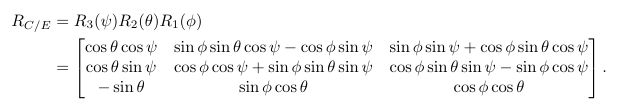

R_ce = [ cos(psi)   -sin(psi) 0; sin(psi) cos(psi) 0; 0 0 1;] * ...
       [cos(theta) 0 sin(theta); 0 1 0; -sin(theta) 0 cos(theta);] * ...
       [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi);]

$$R\_ce = \left(\begin{array}{ccc} \cos\left(\psi \right)\,\cos\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\varphi \right)\,\sin\left(\theta \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)+\sin\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\varphi \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) \end{array}\right)$$


syms x1 x2 x3 alpha1 alpha2 alpha3 v1 v2 v3 omega1 omega2 omega3
syms g l m u1 u2 u3 u4 sigma n1 n2 n3 r1 r2 r3 Ix Iy Iz

e1 = [1; 0; 0;];
e2 = [0; 1; 0;];
e3 = [0; 0; 1;];

c1 = [1; 0; 0;];
c2 = [0; 1; 0;];
c3 = [0; 0; 1;];

% c1 = R_ce*c1;
% c2 = R_ce*c2;
% c3 = R_ce*c3;

n = [n1; n2; n3;];
r = [r1; r2; r3;];

n = [0; 0; 0;];
r = [0; 0; 0;];

I = [Ix 0 0; 0 Iy 0; 0 0 Iz;];

omega = [omega1; omega2; omega3;]

$$omega = \left(\begin{array}{c} \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$


x = [x1; x2; x3; alpha1; alpha2; alpha3; v1; v2; v3; omega1; omega2; omega3;]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ \alpha_{1}\\ \alpha_{2}\\ \alpha_{3}\\ v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

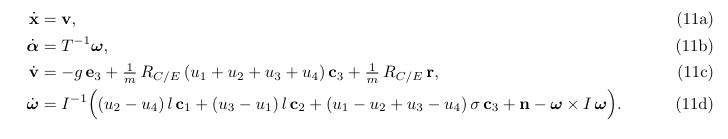

xdot = [v1; v2; v3;]

$$xdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3} \end{array}\right)$$

alphadot = T_inv * [omega1; omega2; omega3;]

$$alphadot = \left(\begin{array}{c} \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)} \end{array}\right)$$


vdot= simplify(-g*e3 + (1/m)*R_ce*(u1+u2+u3+u4)*c3+(1/m)*R_ce*r)

$$vdot = \left(\begin{array}{c} \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g \end{array}\right)$$


omegadot = inv(I)*( (u2-u4)*l*c1+(u3-u1)*l*c2+(u1-u2+u3-u4)*sigma*c3+n-cross(omega, I*omega))

$$omegadot = \left(\begin{array}{c} \frac{l\,\left(u_{2}-u_{4}\right)+\mathrm{Iy}\,\omega_{2}\,\omega_{3}-\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{3}-\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{2}-\mathrm{Iy}\,\omega_{1}\,\omega_{2}}{\mathrm{Iz}} \end{array}\right)$$


simplify(omegadot)

$$ans = \left(\begin{array}{c} \frac{l\,\left(u_{2}-u_{4}\right)+\mathrm{Iy}\,\omega_{2}\,\omega_{3}-\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{3}-\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{2}-\mathrm{Iy}\,\omega_{1}\,\omega_{2}}{\mathrm{Iz}} \end{array}\right)$$

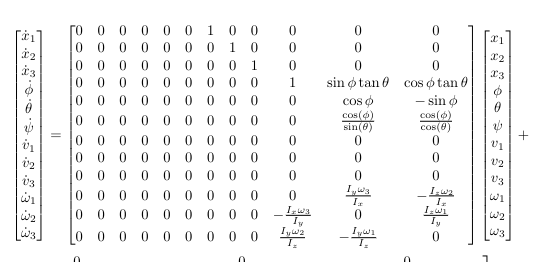

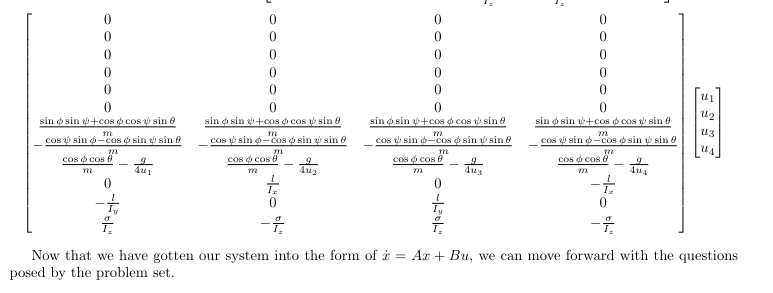

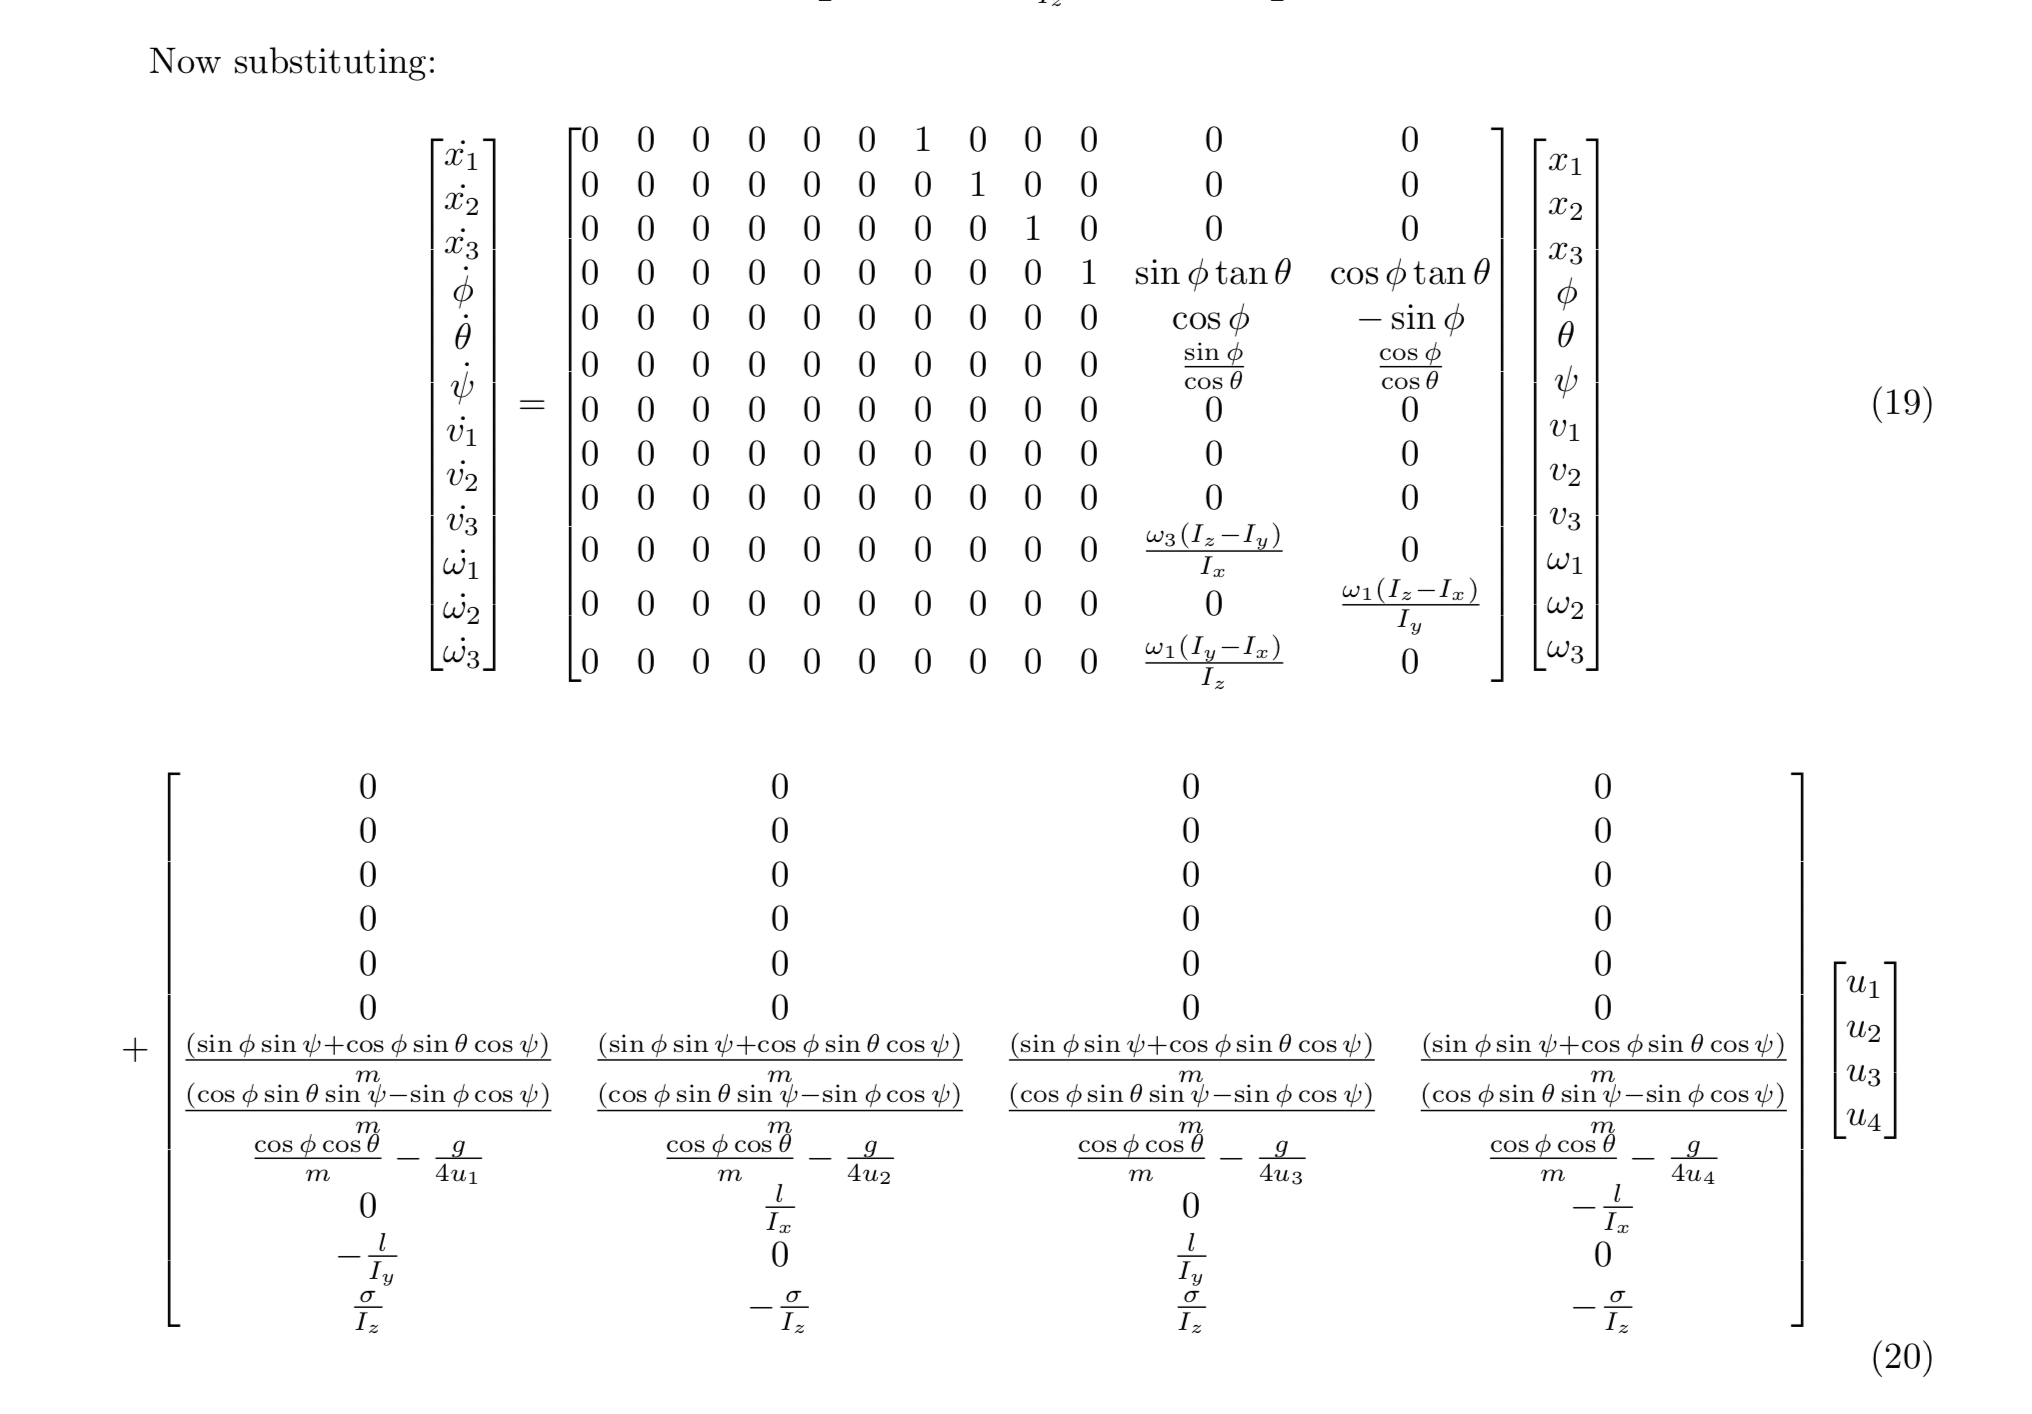

% A = [
%         0   0   0   0   0   0   1   0   0   0   0   0;
%         0   0   0   0   0   0   0   1   0   0   0   0;
%         0   0   0   0   0   0   0   0   1   0   0   0;
%         0   0   0   0   0   0   0   0   0   1   sin(phi)*tan(theta) cos(phi)*tan(theta);
%         0   0   0   0   0   0   0   0   0   0   cos(phi)            -sin(phi);
%         0   0   0   0   0   0   0   0   0   0   cos(phi)/sin(theta) cos(phi)/cos(theta);
%         0   0   0   0   0   0   0   0   0   0   0   0;
%         0   0   0   0   0   0   0   0   0   0   0   0;
%         0   0   0   0   0   0   0   0   0   0   0   0;
%         0   0   0   0   0   0   0   0   0   0   (omega3*(Iy-Ix))/Ix 0;
%         0   0   0   0   0   0   0   0   0   0   0   (omega1*(Iz-Ix))/Iy;
%         0   0   0   0   0   0   0   0   0   0   (omega1*(Iy-Ix))/Ix 0;
%     ]

A = [
        0   0   0   0   0   0   1   0   0   0   0   0;
        0   0   0   0   0   0   0   1   0   0   0   0;
        0   0   0   0   0   0   0   0   1   0   0   0;
        0   0   0   0   0   0   0   0   0   1   sin(phi)*tan(theta) cos(phi)*tan(theta);
        0   0   0   0   0   0   0   0   0   0   cos(phi)            -sin(phi);
        0   0   0   0   0   0   0   0   0   0   cos(phi)/sin(theta) cos(phi)/cos(theta);
        0   0   0   0   0   0   0   0   0   0   0   0;
        0   0   0   0   0   0   0   0   0   0   0   0;
        0   0   0   0   0   0   0   0   0   0   0   0;
        0   0   0   0   0   0   0   0   0   0   (Iy*omega3)/Ix  (Iz*omega2)/Ix;
        0   0   0   0   0   0   0   0   0   -(Ix*omega3)/Iy 0   (Iz*omega1)/Iy;
        0   0   0   0   0   0   0   0   0   (Iy*omega2)/Iz  (-Iy*omega1)/Iz 0;
    ]

$$A = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & \sin\left(\varphi \right)\,\tan\left(\theta \right) & \cos\left(\varphi \right)\,\tan\left(\theta \right)\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{\cos\left(\varphi \right)}{\sin\left(\theta \right)} & \frac{\cos\left(\varphi \right)}{\cos\left(\theta \right)}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{\mathrm{Iy}\,\omega_{3}}{\mathrm{Ix}} & \frac{\mathrm{Iz}\,\omega_{2}}{\mathrm{Ix}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & -\frac{\mathrm{Ix}\,\omega_{3}}{\mathrm{Iy}} & 0 & \frac{\mathrm{Iz}\,\omega_{1}}{\mathrm{Iy}}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & \frac{\mathrm{Iy}\,\omega_{2}}{\mathrm{Iz}} & -\frac{\mathrm{Iy}\,\omega_{1}}{\mathrm{Iz}} & 0 \end{array}\right)$$


B = [
        0   0   0   0;
        0   0   0   0;
        0   0   0   0;
        0   0   0   0;
        0   0   0   0;
        0   0   0   0;
        (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m  (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m  (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m  (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m;
        -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m;
        ((cos(phi)*cos(theta))/m)-(g/(4*u1))    ((cos(phi)*cos(theta))/m)-(g/(4*u2))    ((cos(phi)*cos(theta))/m)-(g/(4*u3))    ((cos(phi)*cos(theta))/m)-(g/(4*u4));
        0   l/Ix    0   -l/Ix;
        -l/Iy   0   l/Iy    0;
        sigma/Iz    -sigma/Iz   sigma/Iz    -sigma/Iz;
    ]

$$B = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ \sigma_{3}-\frac{g}{4\,u_{1}} & \sigma_{3}-\frac{g}{4\,u_{2}} & \sigma_{3}-\frac{g}{4\,u_{3}} & \sigma_{3}-\frac{g}{4\,u_{4}}\\ 0 & \frac{l}{\mathrm{Ix}} & 0 & -\frac{l}{\mathrm{Ix}}\\ -\frac{l}{\mathrm{Iy}} & 0 & \frac{l}{\mathrm{Iy}} & 0\\ \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} & \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{2}=\frac{\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{3}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$


% B = [0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0; 0 0 0 0;
%     (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m      (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m      (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m      (sin(phi)*sin(psi)+cos(phi)*cos(psi)*sin(theta))/m;
%     -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m     -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m     -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m     -(cos(psi)*sin(phi)-cos(phi)*sin(psi)*sin(theta))/m;
%     (cos(theta)*cos(phi))/m - (g/4*u1)                      (cos(theta)*cos(phi))/m - (g/4*u2)                      (cos(theta)*cos(phi))/m - (g/4*u3)                      (cos(theta)*cos(phi))/m - (g/4*u4);
%     0   0   0   0;  0   0   0   0;  0   0   0   0;]

first_part = A*[x1; x2; x3; phi; theta; psi; v1; v2; v3; omega1; omega2; omega3;]

$$first\_part = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{\omega_{2}\,\cos\left(\varphi \right)}{\sin\left(\theta \right)}\\ 0\\ 0\\ 0\\ \frac{\mathrm{Iy}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}+\frac{\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ \frac{\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}-\frac{\mathrm{Ix}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ 0 \end{array}\right)$$

size(first_part)

ans =     12     1


second_part = B * [u1; u2; u3; u4;]

$$second\_part = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{u_{1}\,\sigma_{2}}{m}+\frac{u_{2}\,\sigma_{2}}{m}+\frac{u_{3}\,\sigma_{2}}{m}+\frac{u_{4}\,\sigma_{2}}{m}\\ -\frac{u_{1}\,\sigma_{1}}{m}-\frac{u_{2}\,\sigma_{1}}{m}-\frac{u_{3}\,\sigma_{1}}{m}-\frac{u_{4}\,\sigma_{1}}{m}\\ -u_{1}\,\left(\frac{g}{4\,u_{1}}-\sigma_{3}\right)-u_{2}\,\left(\frac{g}{4\,u_{2}}-\sigma_{3}\right)-u_{3}\,\left(\frac{g}{4\,u_{3}}-\sigma_{3}\right)-u_{4}\,\left(\frac{g}{4\,u_{4}}-\sigma_{3}\right)\\ \frac{l\,u_{2}}{\mathrm{Ix}}-\frac{l\,u_{4}}{\mathrm{Ix}}\\ \frac{l\,u_{3}}{\mathrm{Iy}}-\frac{l\,u_{1}}{\mathrm{Iy}}\\ \frac{\sigma \,u_{1}}{\mathrm{Iz}}-\frac{\sigma \,u_{2}}{\mathrm{Iz}}+\frac{\sigma \,u_{3}}{\mathrm{Iz}}-\frac{\sigma \,u_{4}}{\mathrm{Iz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$

size(second_part)

ans =     12     1


full = first_part+second_part

$$full = \begin{array}{l} \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{\omega_{2}\,\cos\left(\varphi \right)}{\sin\left(\theta \right)}\\ \frac{u_{1}\,\sigma_{2}}{m}+\frac{u_{2}\,\sigma_{2}}{m}+\frac{u_{3}\,\sigma_{2}}{m}+\frac{u_{4}\,\sigma_{2}}{m}\\ -\frac{u_{1}\,\sigma_{1}}{m}-\frac{u_{2}\,\sigma_{1}}{m}-\frac{u_{3}\,\sigma_{1}}{m}-\frac{u_{4}\,\sigma_{1}}{m}\\ -u_{1}\,\left(\frac{g}{4\,u_{1}}-\sigma_{3}\right)-u_{2}\,\left(\frac{g}{4\,u_{2}}-\sigma_{3}\right)-u_{3}\,\left(\frac{g}{4\,u_{3}}-\sigma_{3}\right)-u_{4}\,\left(\frac{g}{4\,u_{4}}-\sigma_{3}\right)\\ \frac{l\,u_{2}}{\mathrm{Ix}}-\frac{l\,u_{4}}{\mathrm{Ix}}+\frac{\mathrm{Iy}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}+\frac{\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ \frac{l\,u_{3}}{\mathrm{Iy}}-\frac{l\,u_{1}}{\mathrm{Iy}}-\frac{\mathrm{Ix}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}+\frac{\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,u_{1}}{\mathrm{Iz}}-\frac{\sigma \,u_{2}}{\mathrm{Iz}}+\frac{\sigma \,u_{3}}{\mathrm{Iz}}-\frac{\sigma \,u_{4}}{\mathrm{Iz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\\ \sigma_{3}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$


first_part_again = A*[x1; x2; x3; 0; 0; 0; 0; 0; 0; 0; 0; 0;]

$$first\_part\_again = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

second_part_again = B*[m*g/4; m*g/4; m*g/4; m*g/4;]

$$second\_part\_again = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ g\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\\ -g\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\\ -\frac{g\,m\,\left(\frac{g}{4\,u_{1}}-\sigma_{1}\right)}{4}-\frac{g\,m\,\left(\frac{g}{4\,u_{2}}-\sigma_{1}\right)}{4}-\frac{g\,m\,\left(\frac{g}{4\,u_{3}}-\sigma_{1}\right)}{4}-\frac{g\,m\,\left(\frac{g}{4\,u_{4}}-\sigma_{1}\right)}{4}\\ 0\\ 0\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$

full_again = first_part_again+second_part_again;

% A
% A(4,11)
% diff(A(4,11), phi, theta)
z = [x1; x2; x3; phi; theta; psi; v1; v2; v3; omega1; omega2; omega3;]

$$z = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ \varphi \\ \theta \\ \psi \\ v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$

% zdot=simplify(A * z + B*[u1;u2;u3;u4])
zdot = [xdot; alphadot; vdot; omegadot;]

$$zdot = \left(\begin{array}{c} v_{1}\\ v_{2}\\ v_{3}\\ \omega_{1}+\omega_{3}\,\cos\left(\varphi \right)\,\tan\left(\theta \right)+\omega_{2}\,\sin\left(\varphi \right)\,\tan\left(\theta \right)\\ \omega_{2}\,\cos\left(\varphi \right)-\omega_{3}\,\sin\left(\varphi \right)\\ \frac{\omega_{3}\,\cos\left(\varphi \right)}{\cos\left(\theta \right)}+\frac{\omega_{2}\,\sin\left(\varphi \right)}{\cos\left(\theta \right)}\\ \frac{\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ -\frac{\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(u_{1}+u_{2}+u_{3}+u_{4}\right)}{m}-g\\ \frac{l\,\left(u_{2}-u_{4}\right)+\mathrm{Iy}\,\omega_{2}\,\omega_{3}-\mathrm{Iz}\,\omega_{2}\,\omega_{3}}{\mathrm{Ix}}\\ -\frac{l\,\left(u_{1}-u_{3}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{3}-\mathrm{Iz}\,\omega_{1}\,\omega_{3}}{\mathrm{Iy}}\\ \frac{\sigma \,\left(u_{1}-u_{2}+u_{3}-u_{4}\right)+\mathrm{Ix}\,\omega_{1}\,\omega_{2}-\mathrm{Iy}\,\omega_{1}\,\omega_{2}}{\mathrm{Iz}} \end{array}\right)$$

A_jacobian = simplify(jacobian(zdot, z))

B_jacobian = simplify(jacobian(zdot, [u1;u2;u3;u4]))

$$B\_jacobian = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \sigma_{2} & \sigma_{2} & \sigma_{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{1} & \sigma_{1} & \sigma_{1}\\ \sigma_{3} & \sigma_{3} & \sigma_{3} & \sigma_{3}\\ 0 & \frac{l}{\mathrm{Ix}} & 0 & -\frac{l}{\mathrm{Ix}}\\ -\frac{l}{\mathrm{Iy}} & 0 & \frac{l}{\mathrm{Iy}} & 0\\ \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} & \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{2}=\frac{\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{m}\\ \sigma_{3}=\frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} \end{array}$$


tmp1 = subs(A_jacobian, z, [x1; x2; x3; 0; 0; 0; 0; 0; 0; 0; 0; 0;])

$$tmp1 = \begin{array}{l} \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & \sigma_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -\sigma_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{u_{1}+u_{2}+u_{3}+u_{4}}{m} \end{array}$$

tmp2 = subs(tmp1, [u1; u2; u3; u4], [m*g/4; m*g/4; m*g/4; m*g/4;])

$$tmp2 = \left(\begin{array}{cccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & g & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -g & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$


tmp3 = subs(B_jacobian, z, [x1; x2; x3; 0; 0; 0; 0; 0; 0; 0; 0; 0;])

$$tmp3 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{m} & \frac{1}{m} & \frac{1}{m} & \frac{1}{m}\\ 0 & \frac{l}{\mathrm{Ix}} & 0 & -\frac{l}{\mathrm{Ix}}\\ -\frac{l}{\mathrm{Iy}} & 0 & \frac{l}{\mathrm{Iy}} & 0\\ \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} & \frac{\sigma }{\mathrm{Iz}} & -\frac{\sigma }{\mathrm{Iz}} \end{array}\right)$$

% jacobian(A, )
% diff(A, phi, theta, psi, omega1, omega2, omega3)
% diff(B, phi, theta, psi, omega1, omega2, omega3)
% 

a = tmp2;
b = tmp3;
C = [b a*b a^2*b a^3*b a^4*b a^5*b a^6*b a^7*b a^8*b a^9*b a^10*b a^11*b ]

size(C)

ans =     12    48


rank(C)

ans = 12